# Main para preprocesamiento de datos de nichos

clear; clc; close all;

### 2. Set the path to the folder containing the layer data

layerfolder = 'data/layers/'

layerfolder = 'data/layers/'

### 3. Read in the layer data from the specified folder using ReadLayers:

-  To execute ReadLayers, there is one required input and three optional inputs.

                Layers = ReadLayers(layer_folder, parallel, nanvalue)

Layers = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 2.662133 seconds.


## Niche generation

### 1. Generate initial point for niche generation using a virtual species method.

- To execute InitialPoint, there is one required input and six optional inputs.

- The default value for method is 'coeff'

 InitialPoint = InitialPoint(layers, method, plotting, random_point, point, coeff, deformations_limit)

#### 1.1 Using Random Coefficients

InfoInitialPoint = InitialPoint(Layers,'harmonic', false);

### 2. Generate the niche map using niche generation algorithm with the initial point

Map = NicheGeneration(Layers, InitialPoint, occupation, plotting)

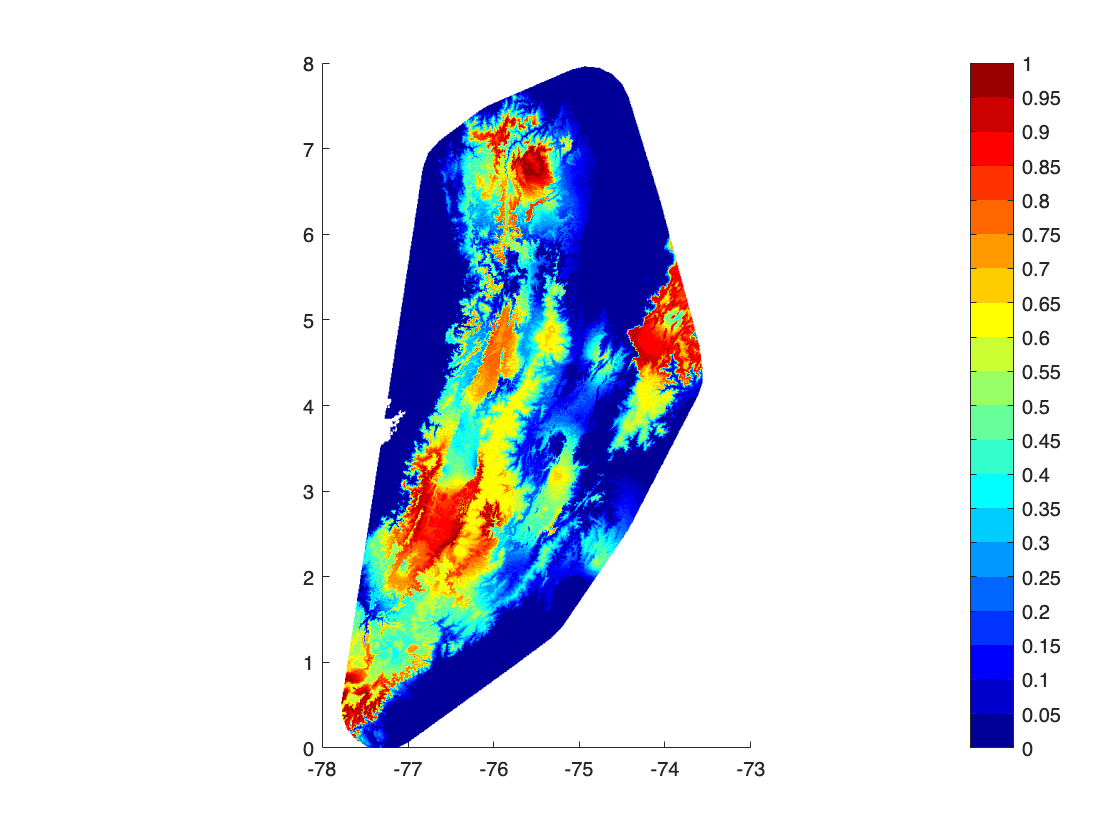

MapInfo = NicheGeneration(Layers, InfoInitialPoint, 0.7, true);

### 2. Generate thesamples in the map

T = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 50, -1, true, 'GenSP', true, true);

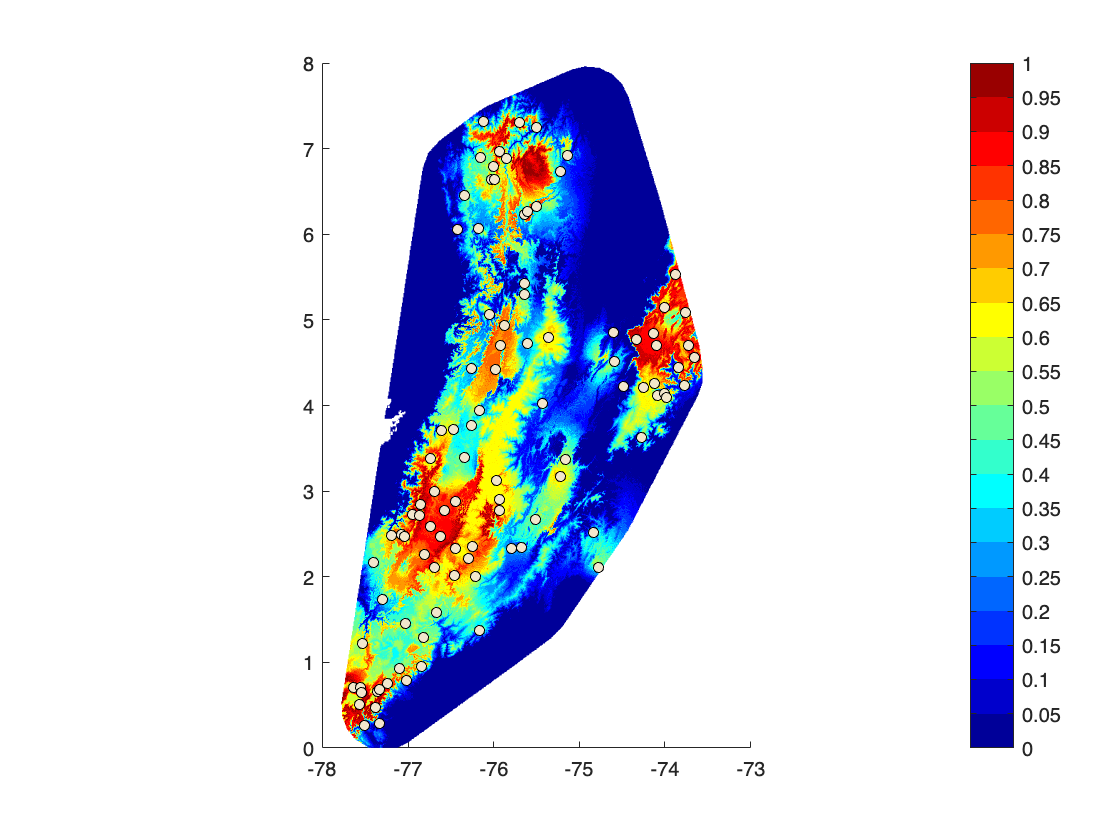

% Sample virtual species using the generated niche map
T = samplingVS(Layers, InfoInitialPoint, MapInfo, 100, -1, true, 'GenSP', true, true);

## Niche Estimation

### 3. Estimate the niche with the sampled points 

% Close all figures
close all, clf

% Show graphics
show=true;

% Remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier1=false;

% Remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier2=false; 

#### Frontier Depth

Frontier Depth `generates a niche probability intensity map, by using the depth of each sample to the samples 3d hull.`

`Estimation = FrontierDepth(SamplePoints,Dimensions,shrinking factor,percent,show,outlier1,outlier2)`

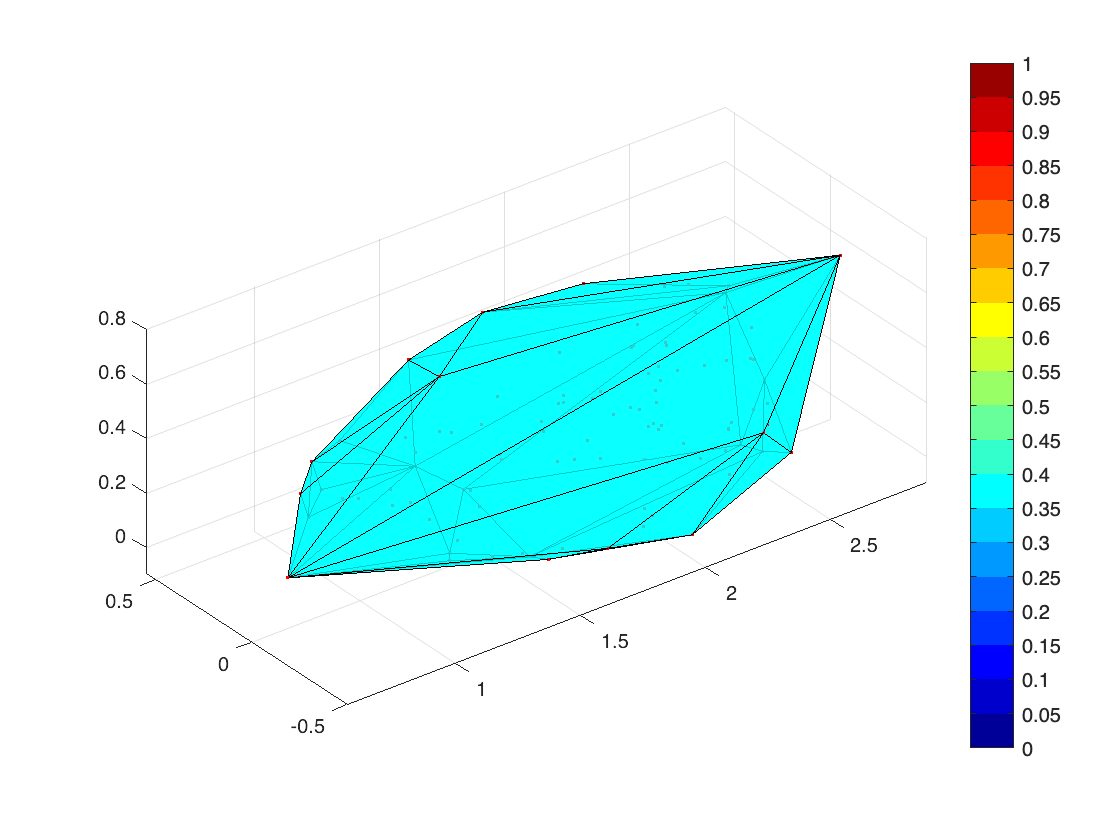

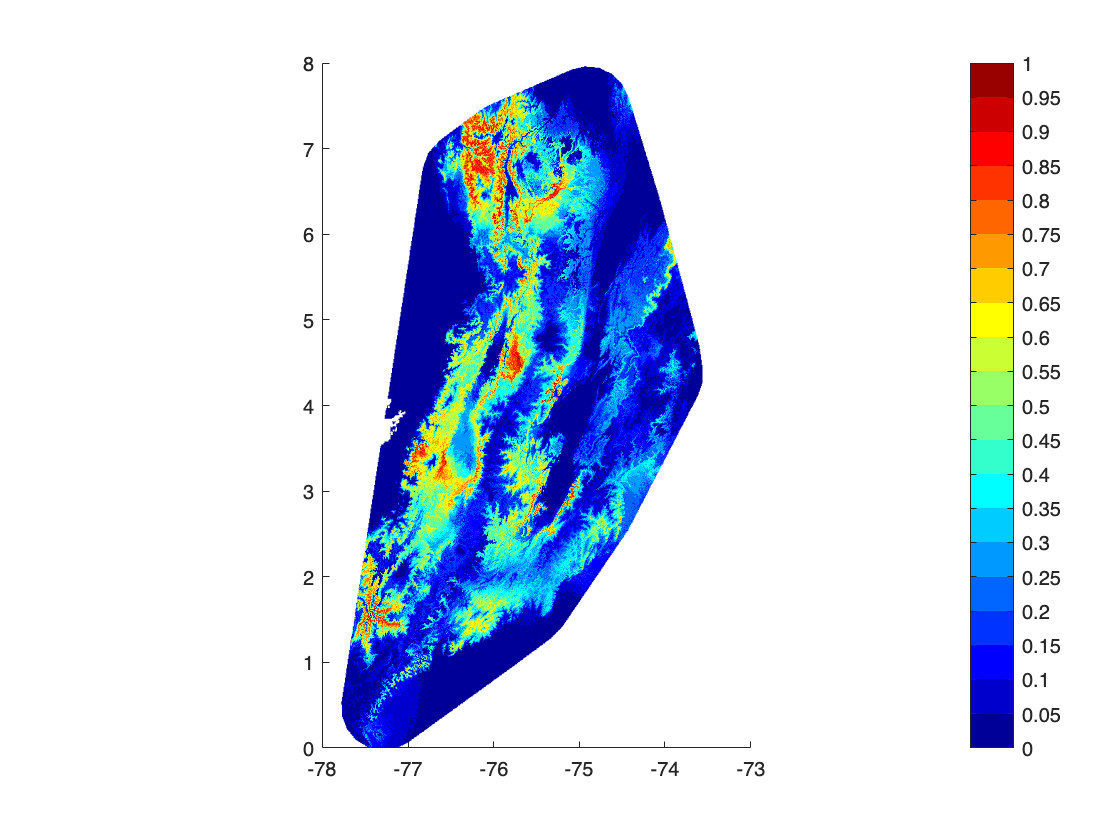

%percentile = percentile 
% with which the radius will be taken
percentile = 1;

Estimation1 = FrontierDepth(T, Layers, 0, percentile, show, outlier1, outlier2); 

Accuracy of the estimated niche

MapMetric(MapInfo.Map,Estimation1.map,false)

ans =     0.8946    0.7422


#### Frontier Depth Average

Frontier Depth `generates a niche probability intensity map, by using the depth of each sample to the samples 3d hull.`

`Estimation = FrontierDepth(SamplePoints,Dimensions,shrinking factor,percent,show,outlier1,outlier2)`

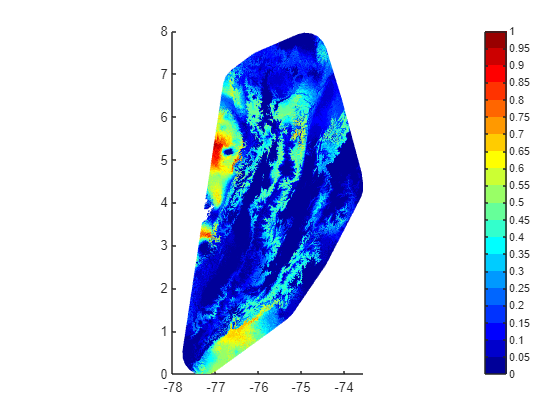

%percentile = percentile from which the radius will be averaged
percentile = 10;

Estimation2 = FrontierDepthAveraged(T,Layers,0,10,show,outlier1,outlier2); 

Accuracy of the estimated niche

MapMetric(MapInfo.Map,Estimation2.map,false)

ans =     0.8223    0.8535


#### Frontier Distance

Frontier Distance `generates a niche probability intensity map, by using the distance of each sample to the samples 3d hull.`

`Estimation = FrontierDistance(SamplePoints,Dimensions,shrinking factor,show,outlier1,outlier2)`

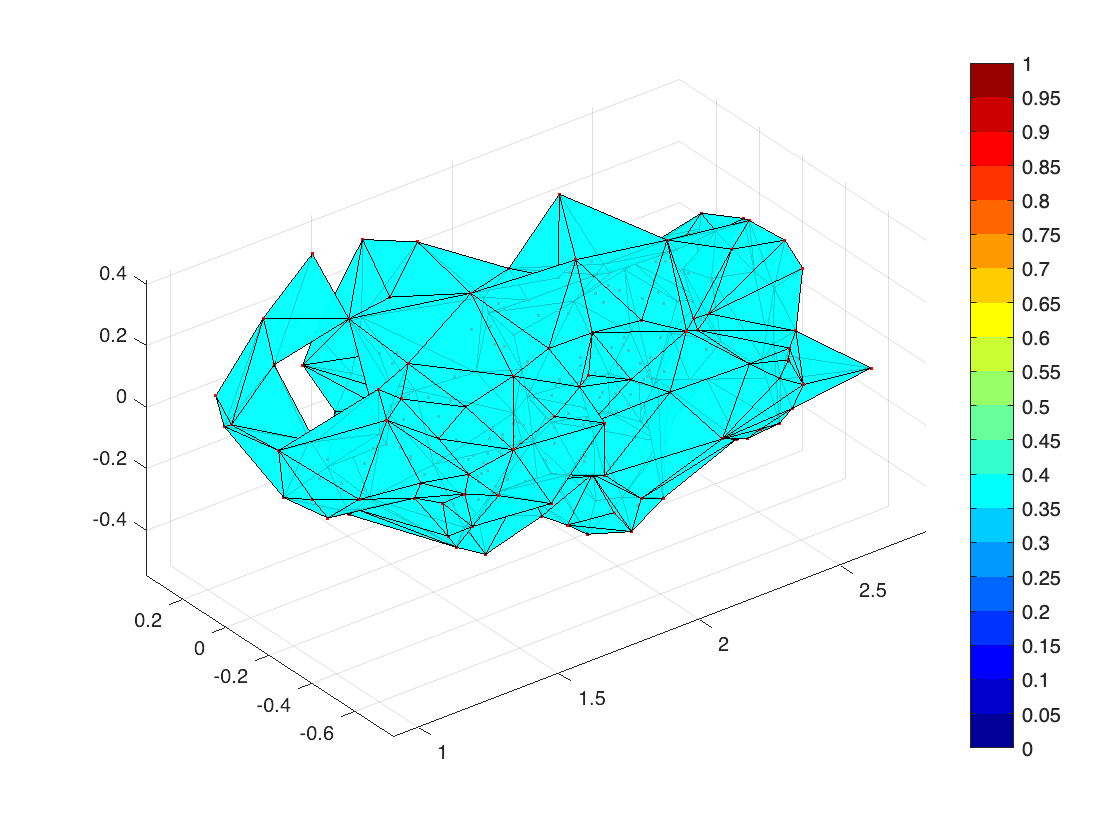

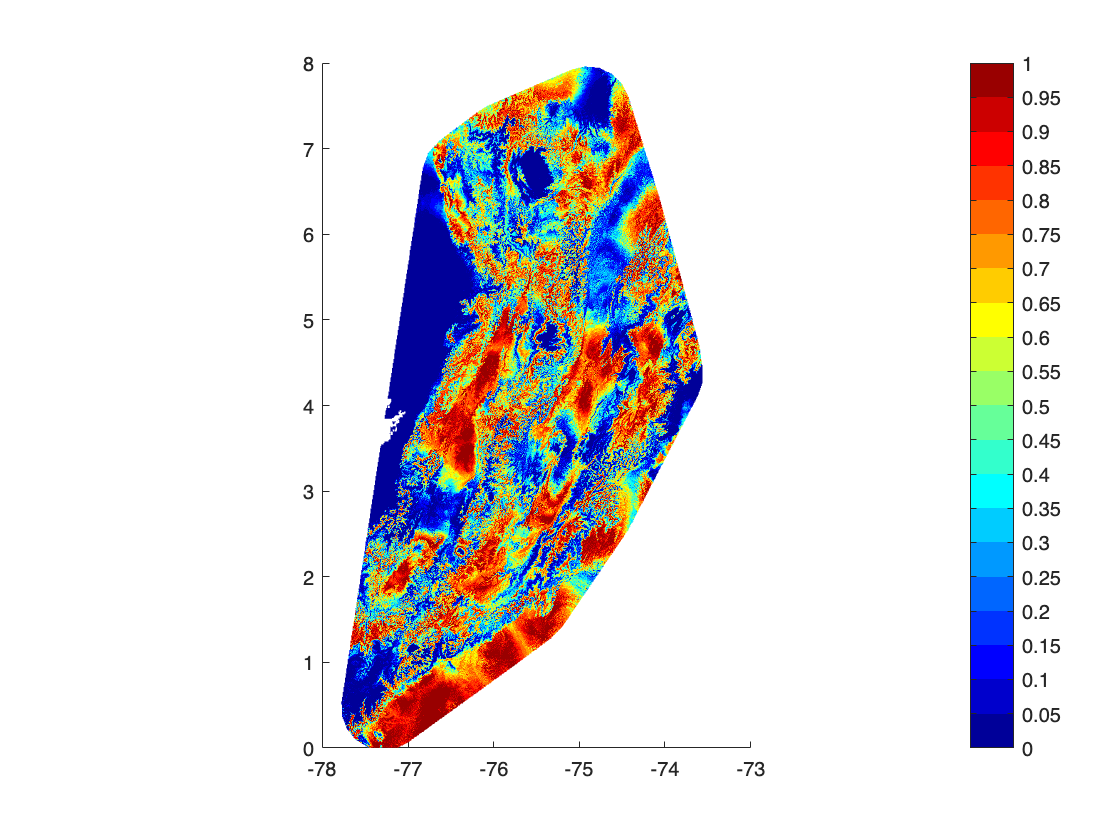

% T = table with samples and information
% readInfo = dimensions of the map
% alpha = shrinking factor

Estimation3 = FrontierDistance(T,Layers,1,true,outlier1,outlier2); 

Accuracy of the estimated niche

MapMetric(MapInfo.Map,Estimation3.map,false)

ans =     0.8838    0.6680
